# Actividad 5: Evaluación robot_1

- **Daniel Castillo López A01737357**

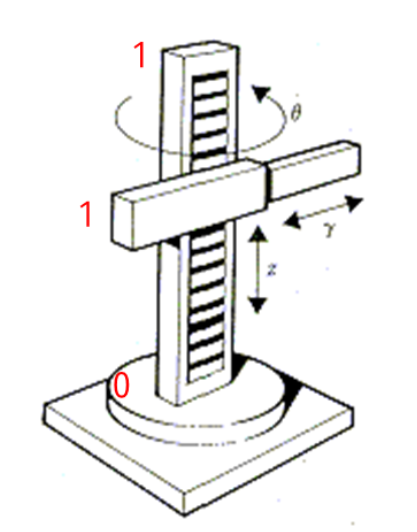

## Inicialización y Declaración de Variables

clear all
close all
clc
syms th1(t) t l1 l2 l3 

Se configura el robot con dos articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y  1 prismático

RP=[0 1 1];
Q= [th1, l2, l3];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
(th1(t), l2, l3)



Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/  d              \
| -- th1(t), 0, 0 |
\ dt              /



GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

Para este caso en particular, usaremos un marco de referencia donde z estrá arriba:


rotacion_z= [cos(th1)  -sin(th1)   0 ;
             sin(th1)   cos(th1)   0 ;
               0            0      1];

 
z_transf= [0  1  0;   %z +90
           1  0  0;
           0  0  1];


transfor_1= rotacion_z*z_transf;
disp(transfor_1);

$$\left(\begin{array}{ccc} -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;th1];

%Matriz de rotación de la junta 1 a 2
R(:,:,1)= transfor_1;

### Articulación 2

x_transf= [1  0  0;   %x -90
           0  0  1;
           0  -1 0];
 
y_transf= [0  0  -1;   %y -90
           0  1  0;
           1  0  0];

transfor_2= y_transf*x_transf;
disp(transfor_2);

     0     1     0
     0     0     1
     1     0     0



%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [0; 0; l2];

%Matriz de rotación de la junta 2 a 3
R(:,:,2)= [0  1  0;
           0  0  1;
           1  0  0];

### Articulación 3 

Para este caso utilizamos la matriz identidad, esto debido a que no hay transformación adicional entre estos sistemas de referencia, lo que significa que los ejes quedan alineados sin modificaciones en posición u orientación.

%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0; l3];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)=   [1  0  0;
             0  1  0;
             0  0  1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty (A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ -sin(th1(t)), cos(th1(t)), 0,    0   \
|                                      |
|  cos(th1(t)), sin(th1(t)), 0,    0   |
|                                      |
|       0,           0,      1, th1(t) |
|                                      |
\       0,           0,      0,    1   /



Matriz de Transformación global T1
/ -sin(th1(t)), cos(th1(t)), 0,    0   \
|                                      |
|  cos(th1(t)), sin(th1(t)), 0,    0   |
|                                      |
|       0,           0,      1, th1(t) |
|                                      |
\       0,           0,      0,    1   /



Matriz de Transformación local A2
/ 0, 1, 0,  0 \
|             |
| 0, 0, 1,  0 |
|             |
| 1, 0, 0, l2 |
|             |
\ 0, 0, 0,  1 /



Matriz de Transformación global T2
/ 0, -sin(th1(t)), cos(th1(t)),      0      \
|                                           |
| 0,  cos(th1(t)), sin(th1(t)),      0      |
|                                           |
| 1,       0,           0,      l2 + th1(t) |
|                                           |
\ 0,       0,           0,           1      /



Matriz de Transformación local A3
/ 1, 0, 0,  0 \
|             |
| 0, 1, 0,  0 |
|             |
| 0, 0, 1, l3 |
|             |
\ 0, 0, 0,  1 /



Matriz de Transformación global T3
/ 0, -sin(th1(t)), cos(th1(t)), l3 cos(th1(t)) \
|                                              |
| 0,  cos(th1(t)), sin(th1(t)), l3 sin(th1(t)) |
|                                              |
| 1,       0,           0,        l2 + th1(t)  |
|                                              |
\ 0,       0,           0,             1       /



## Cálculo del jacobiano lineal y angular de forma analítica

Considerando el tipo de articulación se desarrolla en forma a los vectores, al tener 2 tipos de articulación se desarrolla unicamente en la forma analitica

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
        end

     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ -l3 sin(th1(t)), 0, cos(th1(t)) \
|                                 |
|  l3 cos(th1(t)), 0, sin(th1(t)) |
|                                 |
\        0,        1,      0      /



disp('Jacobiano ángular obtenido de forma analítica'); pretty (Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 0, 0 /



V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/     _________             \
|      d                    |
| -l3 -- th1(t) sin(th1(t)) |
|     dt                    |
|                           |
|     _________             |
|      d                    |
|  l3 -- th1(t) cos(th1(t)) |
|     dt                    |
|                           |
\             0             /



W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



En este caso como el desarrollo del robot se muestra como le 